# README

## Files and directories

## Focus

Inside the code, the `Focus` object is the entry point for interacting with the data. It is simply defined with:

F = Focus('g4dmemf12');

where the first input is a *tag* string containing the identifier of the dataset to focus on. The *tag *can contain filesystem separators (`/` or `\`) to include subdirectories.

NB: verbose can be turned off with

F = Focus('g4gcb', 'verbose', false);

A list of all available tags can be obtained with the static method `Focus.taglist`:

L = Focus.taglist()

L = 1×5 cell array
    {'g4dmemf12'}    {'g4dmemf12-3'}    {'g4dmemf12-4'}    {'g4gcb'}    {'g4gcb-2'}


## Image processing

The code for tracking the pillars is contained in the `+IP` package. The typical routine is embed in the `IP.Routine` script.

A `pTracker` object is created, and the following methods are called sequentially:

- *Initial search*: locate pillars in the first image based on correlation with the average pillar shape. A kernel size `ks` smaller than the one used for the tracking is preferable. A filter based on the value of the correlation is applied (set by the `minCorr` parameter).

- *Defining kernels*: kernels are taken large enough to encompass the whole pillar and a watershed algorithm is used to remove parts of other pilars that may appear at the boundaries.

- *Tracking*

- *Cleaning: *Some trajectories contain `NaN` values, typically at the borders of the image. Their `checked` flag is then turned to `false`.

The result of the tracking is contained in the `pTracker``.P` property and is saved in the file `Focus``.File.trajectories` mat-file (located under the `Root``/Files/` folder). `P` is a structure vectore where each element represents a pillar and has the following fields:

- `x        `The x-coordinate trace (vector)

- `y        `The y-coordinate trace (vector)

- `c0       `The value of the correlation with the average kernel shape during the inital searching step (scalar)

- `K        `The corresponding kernel (array)

- `checked  `A boolean flag used to filter the pilars kept during subsequent analysis (scalar). `true` means that the pillar is kept, while `false` means it is discarded.

## Post-processing

The `GUI.Selector` object allows to visualy check the quality of the tracking, manually define the pillars selected for subsequent analysis and to define a new pillar or re-define a kernel asociated to a pillar and perform a new tracking over this single pillar.

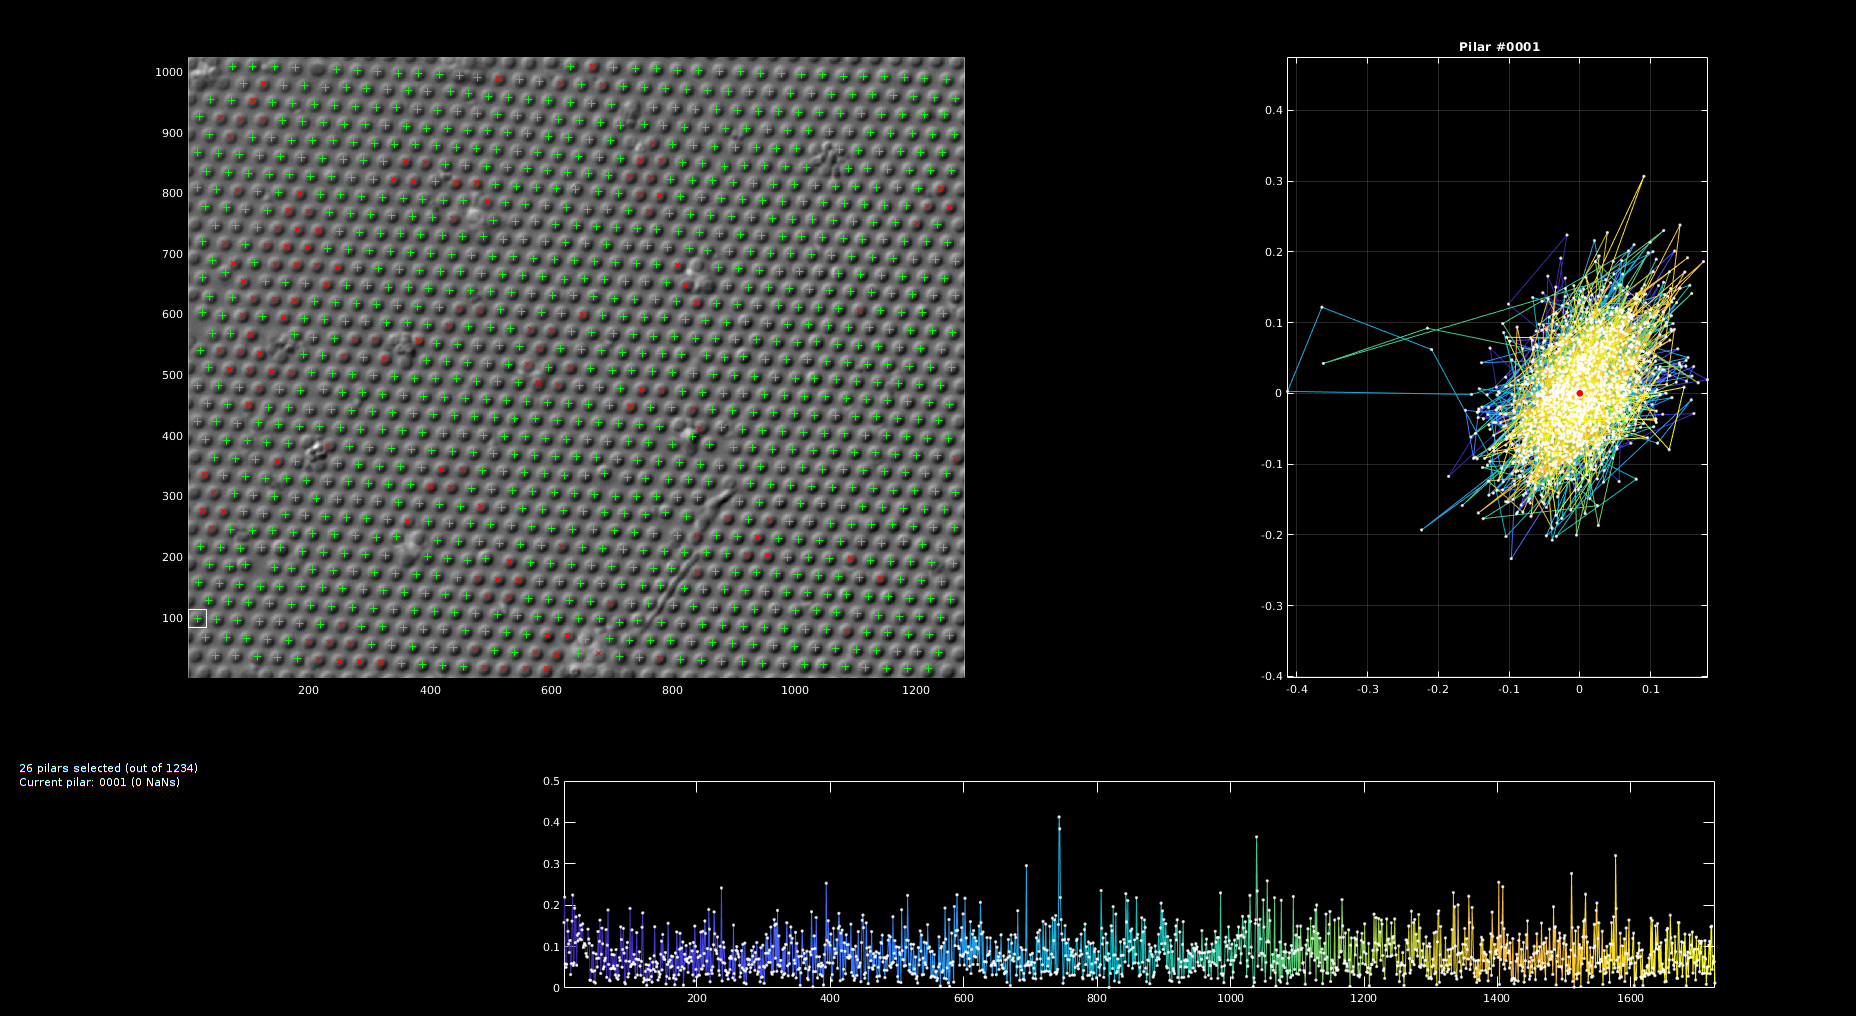

GUI.Selector(F);

Shortcuts:

- `left click        `On the global panel, selects the current pillar.

- `middle click `or` z`: Toggle zoom state (global and trace panels)

- `right click       `Toggle `checked` state of the nearest pillar (global panel) or of the current pillar (other panels)

- `b         `Toggle baseline view

- `k         `Toggle kernel wiew for the current pillar

- `p         `Define a polygon and perform an action. On the global view the action is to toggle the `checked` state of the englobed pillars while on the kernel view it redefines the kernel of the current pillar.

- `r         `Run the tracking for the current pillar (erase the previous trajectory).

- `Ctrl+s    `Save the modified trajectories. **This is mandatory to modify the content of **`Focus``.Files.trajectories`** ! **Otherwise the modifications are lost upon exit.

- `Escape    `Quit (close the GUI)       

## Baseline

The baseline is computed with a running median filter.

The window size is a critical parameter to adjust. The following scripts are helpful:

IP.baseline_windowSize_samples      % Samples with and without events from g4dmemf12
IP.baseline_windowSize_single       % Check the first eigenvalue for all pillars of a single run
IP.baseline_windowSize_all          % Compare the std of the first eigenvalue for several runs